# Problem 2: Simplified landing gear truss

clc;clear;
syms W x R1 R2 R3 Q E I A L M Rh P x1 real

## a) Bending and Axial Deflection of the structure at the point of attachment O.

NOTE : Taking dummy loads Q and P in the direction x and z direction respectively.

M1 = 2*W*x;
M2 = 2*W*x + Q*(x-L) - R3*sind(45)*(x-L) - R2*sind(45)*(x-L);

N1 = W;
N2 = R2*cosd(45) - R3*cosd(45) + W - P;

U1 = simplify(int(M1^2,x,0,L) + int(M2^2,x,L,2*L));
U2 = simplify(int(N1^2,x,0,L) + int(N2^2,x,L,2*L));

U = simplify(1/(2*E*I)*(U1) + 1/(2*E*A)*(U2));

Eq1 = diff(U,R2) == R2*L/(cosd(45)*E*A);
Eq2 = diff(U,R3) == R3*L/(cosd(45)*E*A);

temp = solve([Eq2,Eq1],[R2,R3]);
R2_temp = simplify(temp.R2);
R3_temp = simplify(temp.R3);

U_val = subs(U,[R3,R2],[R3_temp,R2_temp]);
bend_temp = simplify(diff(U_val,Q));
Def_bend = subs(bend_temp,Q,0)

$$Def\_bend = \frac{30\,\text{I}\,L^{3}\,W\,\left(A^{2}\,L^{4}+6\,\sqrt{2}\,A\,\text{I}\,L^{2}+18\,{\text{I}}^{2}\right)}{\text{E}\,{\left(18\,{\text{I}}^{2}-A^{2}\,L^{4}\right)}^{2}}$$


axial_temp = simplify(diff(U_val,P));
Def_axial = subs(axial_temp,P,0)

$$Def\_axial = -\frac{2\,L\,W\,\left(2\,\sqrt{2}+3\right)}{A\,\text{E}}$$

## b) Plotting all the Bending Stresses and Axial Stresses in all sub-stuctures

PLEASE NOTE : The position x here goes left to right, so x=0 denotes the free end, x=2 denotes the fixed end.

*Also taking example values to plot.*

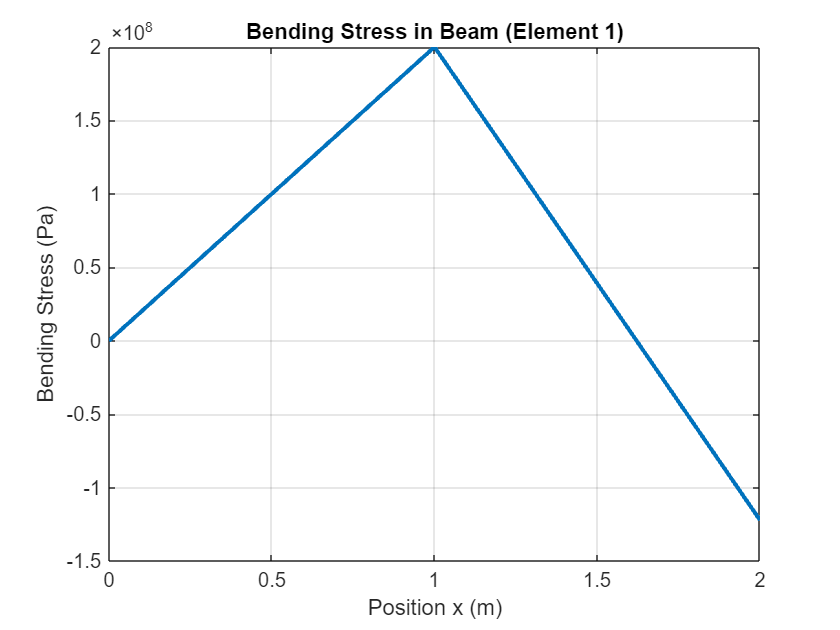

%STRESS DISTRIBUTION (Beam)
E_val = 210e9;      % Young's modulus (Pa)
I_val = 1e-6;       % Area moment of inertia (m^4)
A_val = 1e-4;       % Cross-sectional area (m^2)
L_val = 1;          % Length (m)
W_val = 1000;       % Applied load (N)
y_val = 0.1;        % Distance from neutral axis to outer fiber (m)

R2_val = subs(R2_temp,[W,L,I,A,Q,P],[W_val,L_val,I_val,A_val,0,0]);
R3_val = subs(R3_temp,[W,L,I,A,Q,P],[W_val,L_val,I_val,A_val,0,0]);

M1_val = subs(M1,W,W_val);
M2_val = subs(M2,[W,R2,R3,L,Q],[W_val,R2_val,R3_val,L_val,0]);

N1_val = subs(N1,W,W_val);
N2_val = subs(N2,[R2,R3,W,P],[R2_val,R3_val,W_val,0]);

x_vals = 0:0.01:(2*L_val);

%Element 1
sigma_bend = zeros(1,length(x_vals));
sigma_axial = zeros(1,length(x_vals));

for i = 1:length(x_vals)
    if x_vals(i) <= L_val
        M = double(subs(M1_val, {x}, {x_vals(i)}));
        N = double(subs(N1_val, {x}, {x_vals(i)}));
    else
        M = double(subs(M2_val, {x}, {x_vals(i)}));
        N = double(subs(N2_val, {x}, {x_vals(i)}));
    end
    sigma_bend(i) = M * y_val / I_val;
    sigma_axial(i) = N / A_val;
end

figure;

plot(x_vals, sigma_bend, 'LineWidth', 2);
title('Bending Stress in Beam (Element 1)');
xlabel('Position x (m)');
ylabel('Bending Stress (Pa)');
grid on;

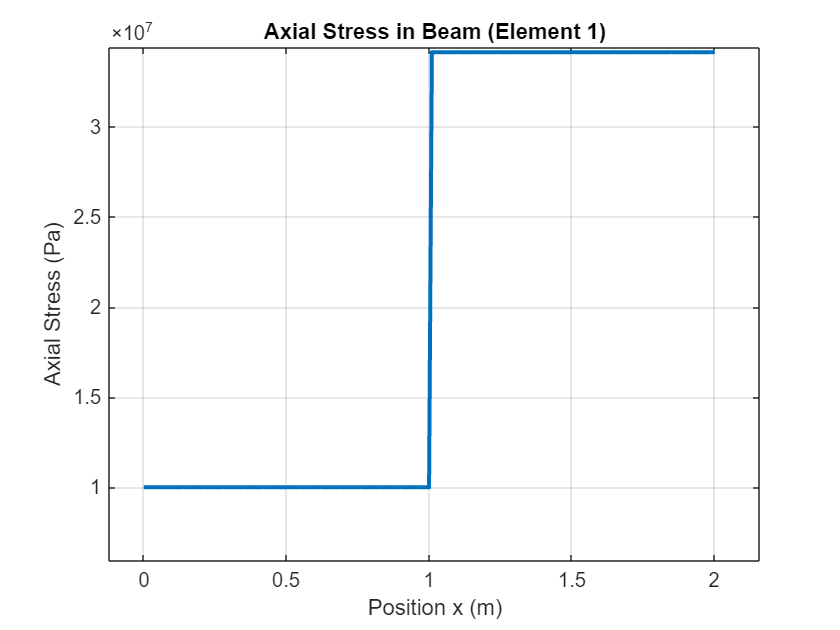


plot(x_vals, sigma_axial, 'LineWidth', 2);
title('Axial Stress in Beam (Element 1)');
xlabel('Position x (m)');
ylabel('Axial Stress (Pa)');
grid on;

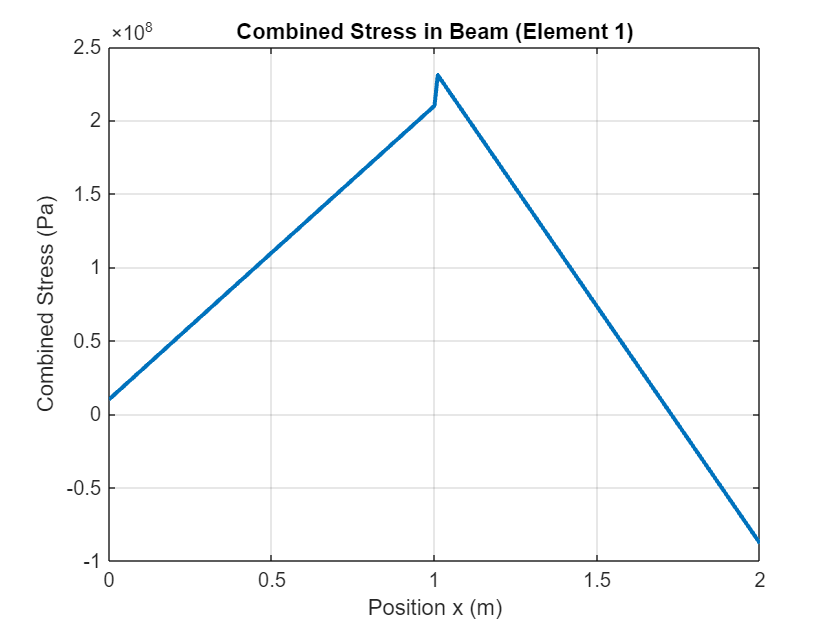


plot(x_vals, sigma_axial + sigma_bend, 'LineWidth', 2);
title('Combined Stress in Beam (Element 1)');
xlabel('Position x (m)');
ylabel('Combined Stress (Pa)');
grid on;

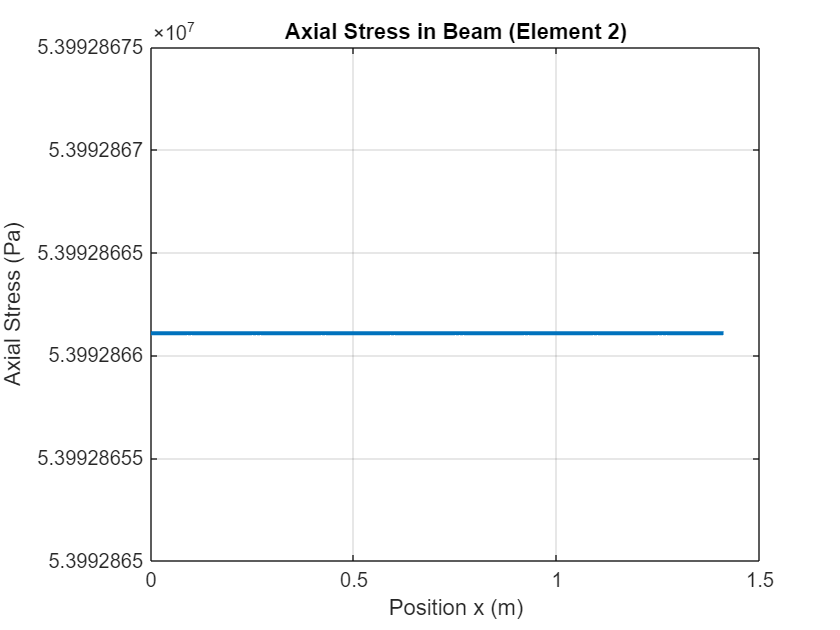


%STRESS DISTRIBUTION Element 2
x_vals = 0:0.01:(L_val/cosd(45));
sigma2 = zeros(1,length(x_vals));
figure;
for i = 1:length(x_vals)
    sigma2(i) = R2_val / A_val;    
end

plot(x_vals, sigma2, 'LineWidth', 2);
title('Axial Stress in Beam (Element 2)');
xlabel('Position x (m)');
ylabel('Axial Stress (Pa)');
grid on;

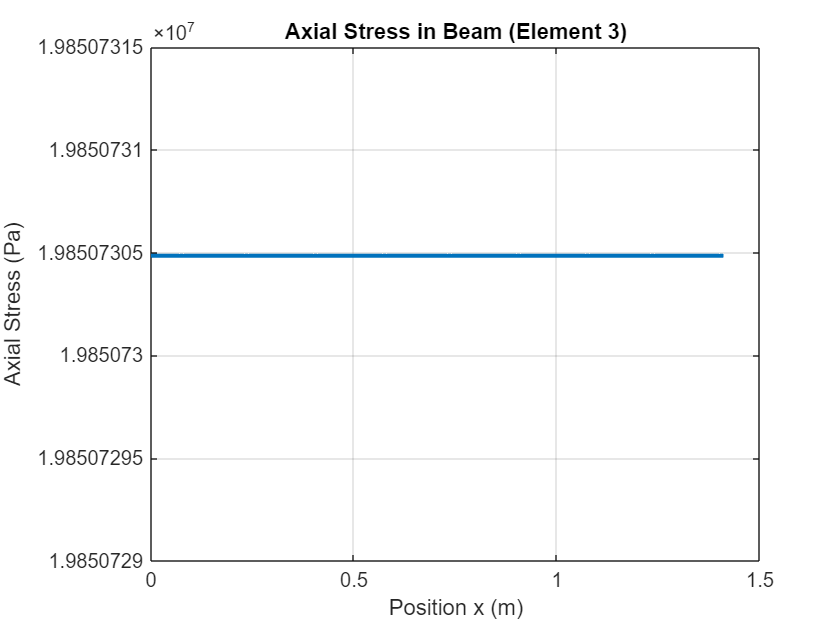


%STRESS DISTRIBUTION Element 3
x_vals = 0:0.01:(L_val/cosd(45));
sigma3 = zeros(1,length(x_vals));
figure;
for i = 1:length(x_vals)
    sigma3(i) = R3_val / A_val;    
end

plot(x_vals, sigma3, 'LineWidth', 2);
title('Axial Stress in Beam (Element 3)');
xlabel('Position x (m)');
ylabel('Axial Stress (Pa)');
grid on;